clear;clc;close all;
ia1=0;ia2=0;ia3=0;ia4=0;ia5=0;dat_nosol=0*(1:6);

U0=20e3;ratioXR=8;

Scc=5e6*(exp(j*atan(ratioXR)));

%Scc=5e9*(exp(j*atan(ratioXR))); % Strong grid

Sc=2e6;Un=U0;f=50;Lx=50e-3;Rx=3*0;

imax=1;ucmax=1.1;

Sb=Sc;Ub=Un;Zb = (Ub^2)/Sb;Zth=U0^2/conj(Scc);
zx = 2*(Rx+ j*2*pi*f*Lx)/Zb;zth= Zth/Zb;
zeq = zth;req=real(zeq);xeq=imag(zeq);
ueq = U0/Ub;


NN=150;
for ii1=1:NN+1
    for ii2=1:NN+1
        p = (ii1-1)*(2/NN)-1;
        q = (ii2-1)*(2/NN)-1;
        a=1;b= (2*req*p+2*xeq*q-abs(ueq)^2);c= (req^2+xeq^2)*(p^2+q^2);
        pol = [a 0 b 0 c];sol = roots(pol);        
        if (imag(sol(1))==0)
            uc = max(sol); 
            zc = uc^2/(p-j*q);    
            ig = - ueq / (zc+zeq);
            ug = ueq + zth * ig;
            uc = ueq + (zth+zx) * ig;
            sc1 = uc * conj(-ig); 
            i_ok=(abs(ig)<=imax);
            u_ok=(abs(uc)<=ucmax);
            if (i_ok&u_ok)
                ia1=ia1+1;
                dat_ok(ia1,1:6)=[ug uc ig -p -q sc1];                    
            end;
            if (i_ok&not(u_ok))
                ia2=ia2+1;
                dat_oki(ia2,1:6)=[ug uc ig -p -q sc1];                       
            end;           
            if (not(i_ok)&u_ok)
                ia3=ia3+1;
                dat_oku(ia3,1:6)=[ug uc ig -p -q sc1];
            end;
            if (not(i_ok)&not(u_ok))
                ia4=ia4+1;
                dat_nok(ia4,1:6)=[ug uc ig -p -q sc1];                      
            end;
        else
            uc=0;ig=0;ug=0;uc0=0;sc1=0;            
            ia5=ia5+1;
            dat_nosol(ia5,1:6)=[ug uc ig -p -q sc1];                    
        end;
   
        dat_pc(ii1,ii2) =real(sc1);
        dat_qc(ii1,ii2) =imag(sc1);
        dat_p(ii1,ii2) =-p;
        dat_q(ii1,ii2) =-q;
        dat_uc(ii1,ii2) =uc;
        dat_ug(ii1,ii2) =ug;
        dat_ig(ii1,ii2) =ig;            
    end;
end;

%% theoretical curves
ii = 0:1:1000;
ang = 2*pi*ii/max(ii);
auxia = imax * exp(j*ang);
auxs = ueq * conj(auxia);
teo_p = real(auxs)

teo_p =     1.0000    1.0000    0.9999    0.9998    0.9997    0.9995    0.9993    0.9990    0.9987    0.9984    0.9980    0.9976    0.9972    0.9967    0.9961    0.9956    0.9950    0.9943    0.9936    0.9929    0.9921    0.9913    0.9905    0.9896    0.9887    0.9877    0.9867    0.9856    0.9846    0.9834    0.9823    0.9811    0.9799    0.9786    0.9773    0.9759    0.9745    0.9731    0.9716    0.9701    0.9686    0.9670    0.9654    0.9637    0.9620    0.9603    0.9585    0.9567    0.9549    0.9530


teo_q = imag(auxs)

teo_q =          0   -0.0063   -0.0126   -0.0188   -0.0251   -0.0314   -0.0377   -0.0440   -0.0502   -0.0565   -0.0628   -0.0691   -0.0753   -0.0816   -0.0879   -0.0941   -0.1004   -0.1066   -0.1129   -0.1191   -0.1253   -0.1316   -0.1378   -0.1440   -0.1502   -0.1564   -0.1626   -0.1688   -0.1750   -0.1812   -0.1874   -0.1935   -0.1997   -0.2059   -0.2120   -0.2181   -0.2243   -0.2304   -0.2365   -0.2426   -0.2487   -0.2548   -0.2608   -0.2669   -0.2730   -0.2790   -0.2850   -0.2910   -0.2970   -0.3030


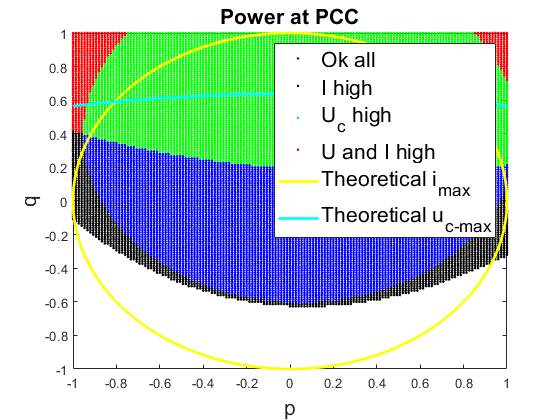



xx=imag(zx);
teo_p2 = -1:.01:1;
teo_q2 =  sqrt((ucmax*ueq/xx).^2-teo_p2.^2) - (ueq^2)/xx;

%[ug uc ig p q sc1]
figure(1);
plot(dat_ok(:,4),dat_ok(:,5),'.b');hold on;
plot(dat_oku(:,4),dat_oku(:,5),'.k');
plot(dat_oki(:,4),dat_oki(:,5),'.g');
plot(dat_nok(:,4),dat_nok(:,5),'.r');
plot(teo_p,teo_q,'y','LineWidth',2);
plot(teo_p2,teo_q2,'c','LineWidth',2); %negative for sign convention
title('Power at PCC','FontSize',16);xlabel('p','FontSize',16);ylabel('q','FontSize',16);
legend('Ok all','I high','U_c high','U and I high','Theoretical i_{max}','Theoretical u_{c-max}','FontSize',16)

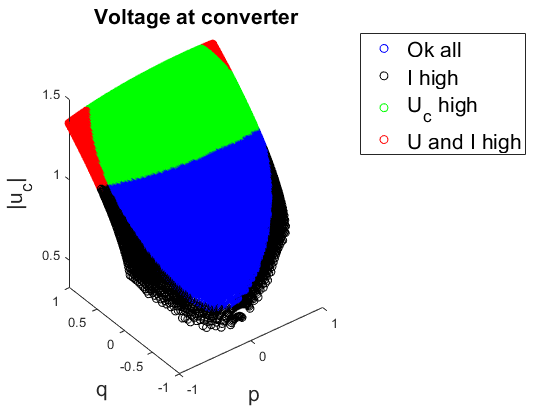



figure(2);
plot3(dat_ok(:,4),dat_ok(:,5),abs(dat_ok(:,2)),'ob');hold on;
plot3(dat_oku(:,4),dat_oku(:,5),abs(dat_oku(:,2)),'ok');
plot3(dat_oki(:,4),dat_oki(:,5),abs(dat_oki(:,2)),'og');
plot3(dat_nok(:,4),dat_nok(:,5),abs(dat_nok(:,2)),'or');
title('Voltage at converter','FontSize',16)
legend('Ok all','I high','U_c high','U and I high','FontSize',16)
xlabel('p','FontSize',16);ylabel('q','FontSize',16);
zlabel('|u_c|','FontSize',16);

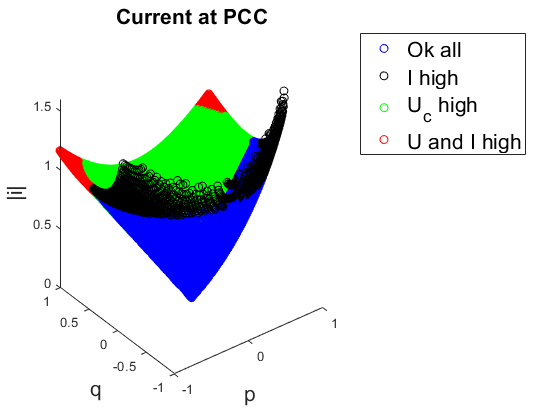


figure(3);
plot3(dat_ok(:,4),dat_ok(:,5),abs(dat_ok(:,3)),'ob');hold on;
plot3(dat_oku(:,4),dat_oku(:,5),abs(dat_oku(:,3)),'ok');
plot3(dat_oki(:,4),dat_oki(:,5),abs(dat_oki(:,3)),'og');
plot3(dat_nok(:,4),dat_nok(:,5),abs(dat_nok(:,3)),'or');
title('Current at PCC','FontSize',16)
legend('Ok all','I high','U_c high','U and I high','FontSize',16)
xlabel('p','FontSize',16);ylabel('q','FontSize',16);
zlabel('|i|','FontSize',16);